# T1 and T2 contrast

When we look at an image, the information is contained in the image contrast - the differences in the image intensity at different positions.  In creating an MR image of the brain, we choose whether the image contrast arises mainly from T1, T2 or PD differences in the brain.  These are the T1-weighted, T2-weighted or PD-weighted images.

How do we calculate this?  For the key pulse sequences we have formulae that predict the expected signal amplitudes if we know the T1 and T2 values of the substrate and the parameters of the sequence. The relationship between these terms is called the **'Signal Equation'.**

This script uses the signal equation from a **Spin-Echo** sequence, in which case the only parameters are TR and TE. 

## Spin Echo signal equation

This is the spin echo pulse sequence - notice the 90 deg followed by the 180 deg RF pulse.  Other aspects of the sequence involving the gradients have to do with imaging, and we will get to that later.

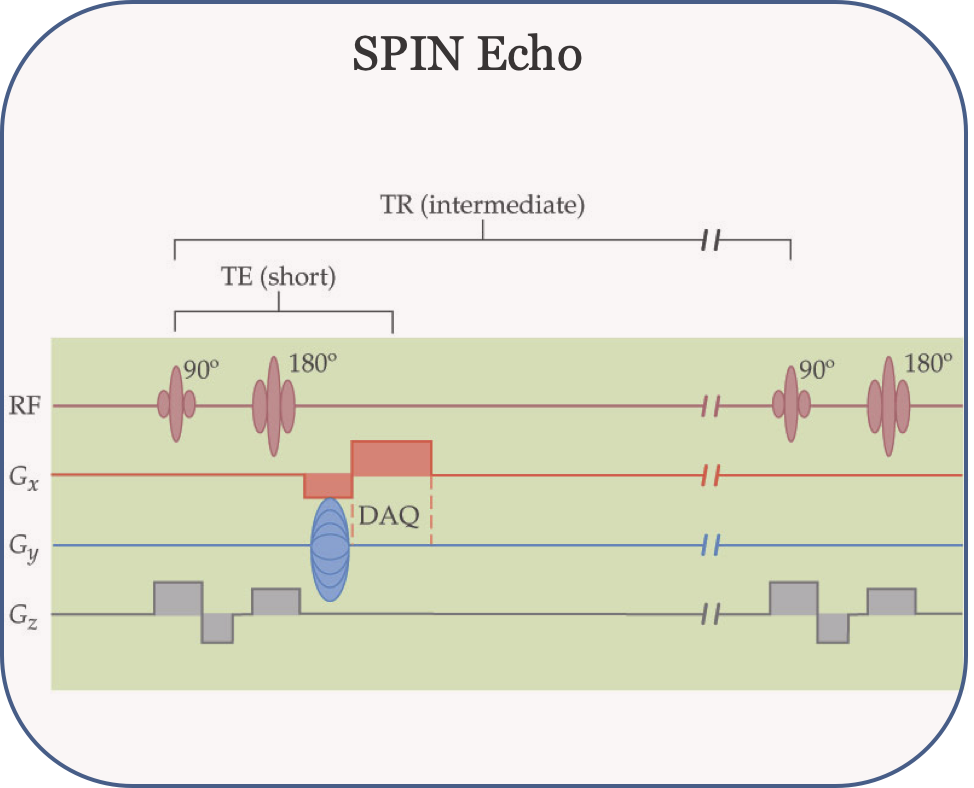

The signal equation for the **Spin Echo** sequence is


$$S=k*\mathrm{PD}*\left(1-\mathrm{exp}\left(-\frac{\mathrm{TR}}{\mathrm{T1}}\right)\right)*\mathrm{exp}\left(-\frac{\mathrm{TE}}{\mathrm{T2}}\right)$$


The parameter k is a constant, and we will ignore it. For this example we are going to simplify things by treating the proton density (PD) as constant across the brain.

(See the [CNI wiki page for gradient echo and inversion recovery signal equations](https://cni.stanford.edu/wiki/MR_Signal_Equations).)

## Exploring the signal equation

The two terms we are going to explore are the exponentials that multiply against one another.  As you can see, the TR is grouped with the T1 value, and TE is grouped with the T2 value.  


$$1-\mathrm{exp}\left(\frac{-\mathrm{TR}}{\mathrm{T1}}\right)$$
 


$$\mathrm{exp}\left(-\frac{\mathrm{TE}}{\mathrm{T2}}\right)$$


When we set TR we will have an impact how much of T1 we measure, and when we set TE we will have an impact on how much of T2 we measure. 

Remember, we are interested in forming an image that has contrast.  When measuring the brain for a structural anatomy, we may particularly interested in choosing parameters that produce a large **difference between the gray and white matter signals. **This image contrast can be based on either the T1 and T2 values for gray and white.  We can calculate these separately because the TR and TE terms are so nicely separated.

**T1 gray-white contrast**:  $\left(1-\mathrm{exp}\left(-\frac{\mathrm{TR}}{\mathrm{grayT1}}\right)\right)-\left(1-\mathrm{exp}\left(-\frac{\mathrm{TR}}{\mathrm{whiteT1}}\right)\right)$

**T2 gray-white contrast**:   $\mathrm{exp}\left(-\frac{\mathrm{TE}}{\mathrm{grayT2}}\right)-\mathrm{exp}\left(-\frac{\mathrm{TE}}{\mathrm{whiteT2}}\right)$

Next we do some calculations to select TR and TE that create good gray-white contrast images based on T1 or T2.

## Tissue properties

We start by setting up the [tissue T1 and T2 tissue parameters of gray and white matter](https://www.ncbi.nlm.nih.gov/pubmed/10232510).

% These are the estimated T1 and T2 for gray matter in a 3T scanner.
gT1 = 1.330; 
gT2 = 0.080; 

% And thse are the values for white matter at 3T
wT1 = 0.8332;
wT2 = 0.110;

% Normally the signal equation accounts for proton density and the units.
% To siimplify, we are going to make PD and k irrelevant for these
% calculations by setting them both to 1.  In reality PD varies across the
% brain and it will play a role in the final image appearance.
PD = 1;      % Proton density
k  = 1;      % Scale factors for units

## The T1 contrast between gray and white 

The TR term determines how much T1 gray-white contrast we measure.  We plot the T1 contrast  (difference between gray and white) for different values of TR. 

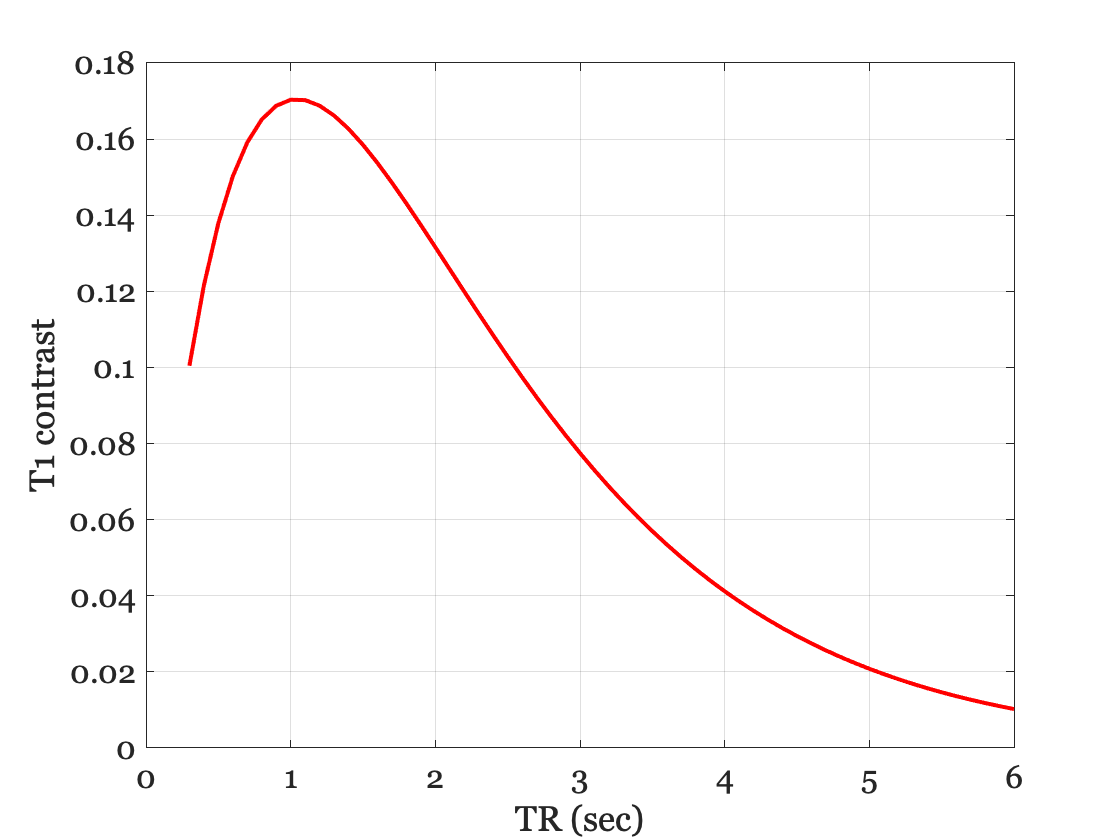

TR = 0.3:0.1:6;
T1contrast = abs((1-exp(-TR/gT1)) - (1 - exp(-TR/wT1)));

figure; plot(TR,T1contrast);
xlabel('TR (sec)'); ylabel('T1 contrast');
grid on;

The T1 contrast peaks when TR is around 1sec and is small when TR is 4-6 sec.

## The T2 contrast between gray and white 

The T2 gray-white contrast we measure varies as TE changes.  The T2 gray-white contrast is largest around 70-110 ms.

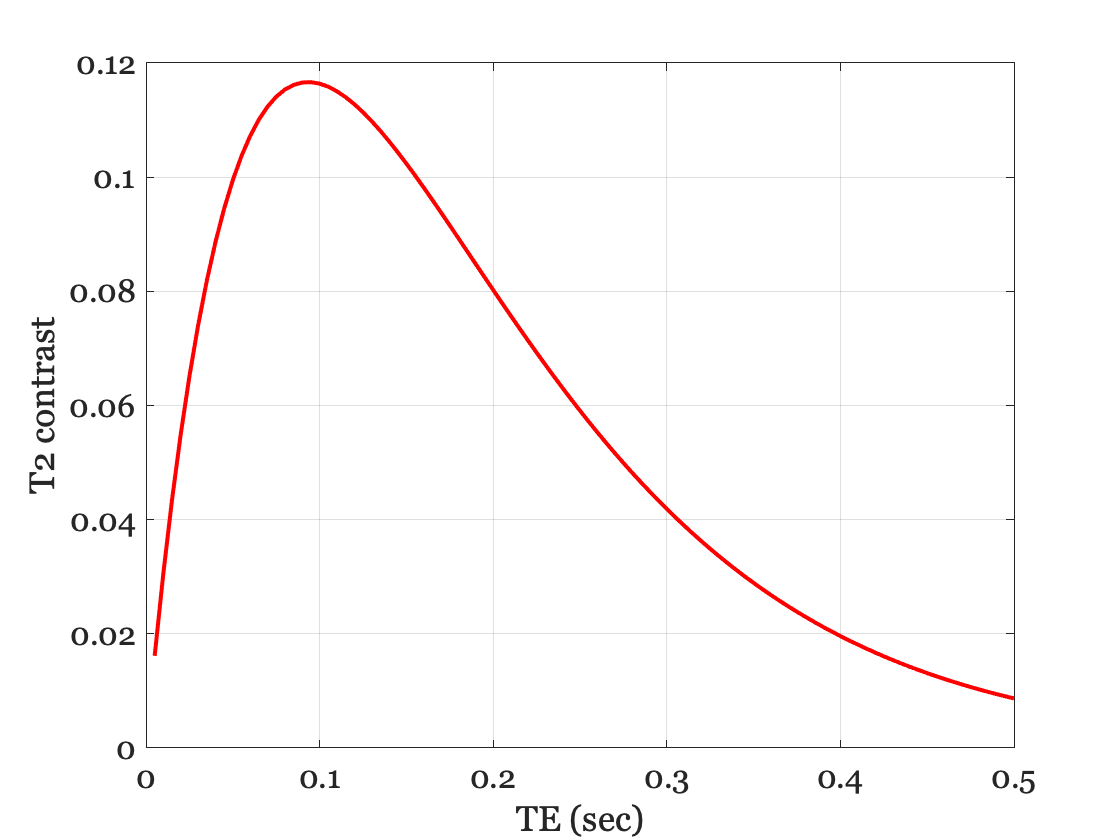

TE = 0.005:0.005:0.500;

T2contrast = abs(exp(-TE/gT2) - exp(-TE/wT2));
figure; 
plot(TE,T2contrast);
xlabel('TE (sec)'); ylabel('T2 contrast');
grid on;

## Creating a T1-weighted contrast image

We have learned that if TR is short (1 sec) the T1 gray-white contrast is relatively **large.  **If TE is short (10-20 ms), the T2 contrast is relatively **small**.  Consequently, we say that a spin-echo sequence with a **short TR** and **short TE** will have a contrast that is **T1-weighted**.  

It is important to notice that what we mean by 'short' differs between TR and TE.  A short TR is around 1 second, while a short TE is around 20 milliseconds.  We try to use numbers with units, rather than qualitative terms like long and short. But life is not always like that.

## The predicted signals

We can use the whole signal equation to predict the gray-white signal difference we measure.  The absolute signal levels may matter to us as well, because it is generally better to have a big signal that is well outside of the noise.  

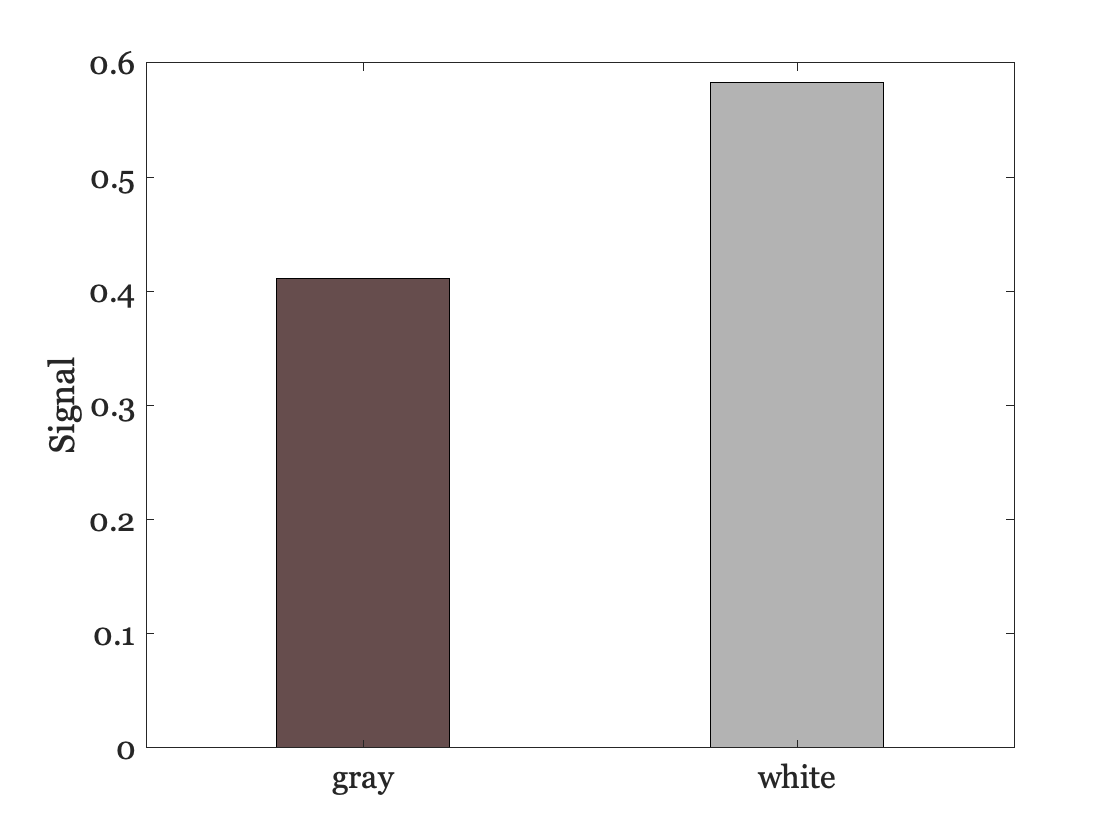

TR = 1;       % Repetition time
TE = 0.020;   % Echo time

% Signal equation, with k and PD ignored
signalGray   = (1 - exp(-TR ./ gT1)) * exp(-TE / gT2);
signalWhite  = (1 - exp(-TR ./ wT1)) * exp(-TE / wT2);

figure; 
X = categorical({'gray','white'});
thisB = bar(X,[signalGray, signalWhite],0.4);
thisB.FaceColor = 'flat';
thisB.CData(1,:) = [0.4 0.3 .3];
thisB.CData(2,:) = [.7 0.7 .7];
ylabel('Signal');

Notice that the difference is about what we expect.  Most of the difference is due to the T1 contrast, but there is a little from T2 as well.

## How the image intensity depends on T1

If we fix the sequence parameters (TR, TE) and measure a T1-weighted contrast, the signal changes with T1 values.  But how?  We can use the signal equation to see the relationship.

I created the variable 't1Steps' to represent different T1 values ranging from white to gray.  Here is how the signal changes as the T1 value changes.  (We use the T2 value from white matter.)

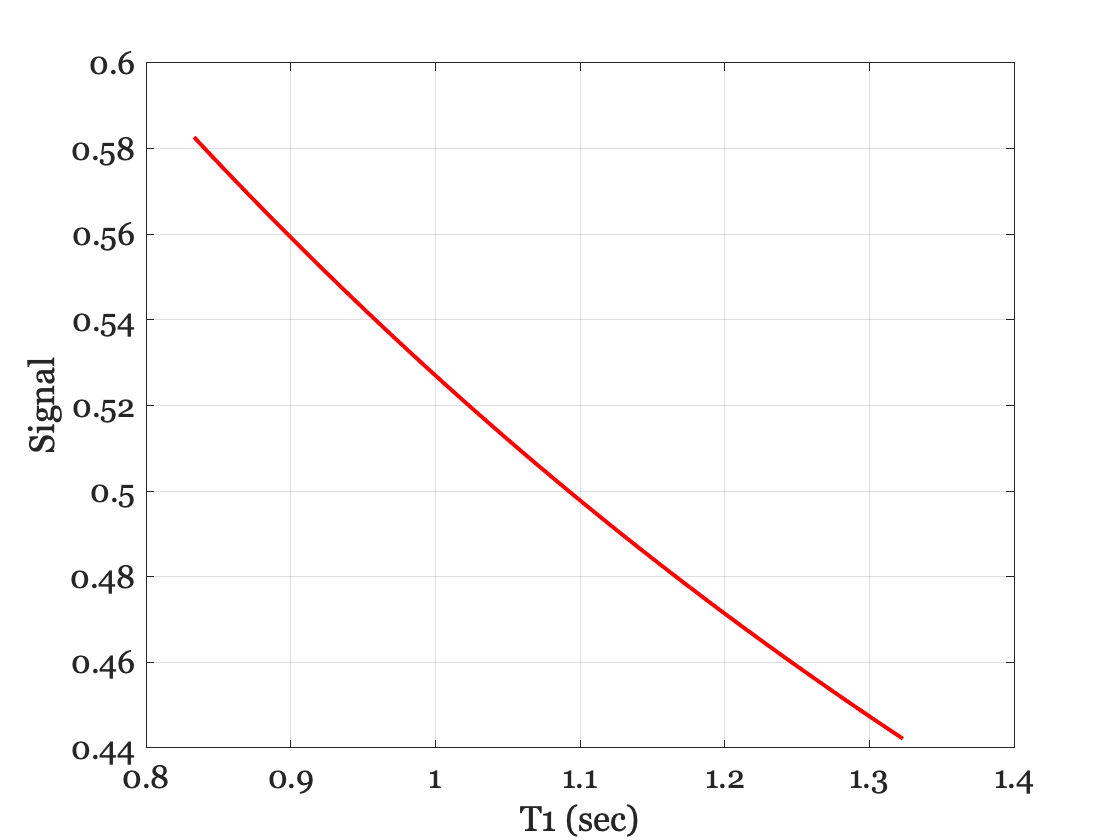

TR = 1;
TE = 0.02;
t1Steps = wT1:0.01:gT1;

% The signal level (not the contrast) depends on T1 this way
signalT1  = k * PD * (1 - exp(- (TR ./ t1Steps))) * exp(-TE / wT2);

figure; 
plot(t1Steps, signalT1); grid on;
xlabel('T1 (sec)'); ylabel('Signal');

As T1 grows, the signal decreases.  This is the reason why when we image T1-weighted data the displayed image intensity is inversely related to T1 value.  Intensity is not proportional to T1 as you might expect.

Also - ask yourself how the values on this curve relate to the two values in the bar chart in the signals predicted section above!

## Creating a T2-weighted contrast

The graphs above show how we can choose TR and TE values that create gray-white based on T2, rather than T1.  When TR is long, the T1 contrast is small.  When TE is about 100 ms, the T2 contrast is large.

% These parameters make T2 contrast bigger than T1 contrast
TR = 5;
TE = 0.100;

% Gray-white difference in T2 signal is substantial.
T2contrast = abs(exp(-TE / gT2) - exp(-TE / wT2))

T2contrast = 0.1164


% Gray-white difference in the T1 signal is much smaller.
T1contrast = abs((1 - exp(-TR ./ gT1)) - (1 - exp(-TR ./ wT1)))

T1contrast = 0.0208

## How image intensity depends on T2 

We calculate how the T2 weighted signal varies with T2 by replacing the single gT2 value with t2Steps.

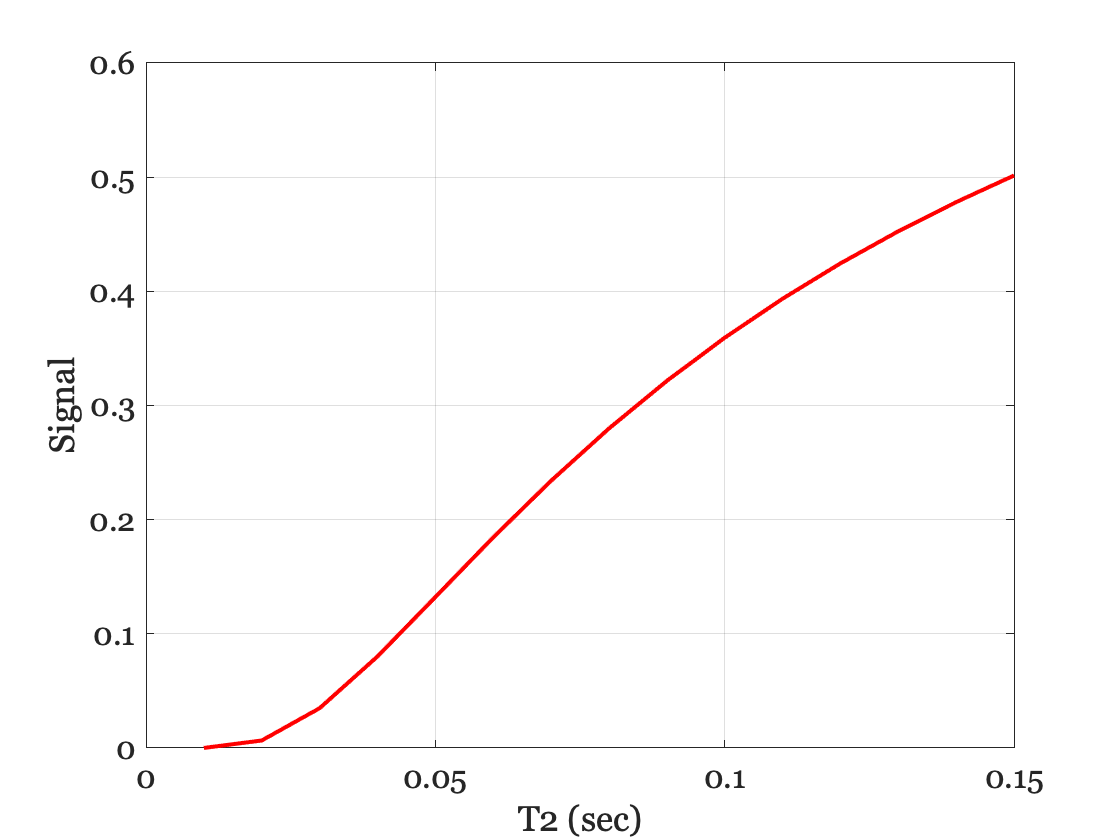

t2Steps = 0.01:0.01:0.15;
t2wSignal = k * PD * (1 - exp(-TR / gT1)) * exp(-TE ./ t2Steps);

figure; plot(t2Steps, t2wSignal); grid on;
xlabel('T2 (sec)'); ylabel('Signal');

In this case the signal intensity increases with T2:  T2-weighted voxels are brighter as T2 increases.  

## Pulse sequence dependence

The signal equations and thus the values we calculate depend on the pulse sequence we use (spin-echo). The signal equations for **Inversion Recovery** and **Gradient Echo** are not the same as Spin Echo.  We would need to recalculate when we use those methods. 

But the principles of how we calculate and use the signal equations is the same which is why this is worth understanding!

## Question

For all the calculations here, we assumed that the proton density (fraction of the voxel filled with water) is a constant across voxels (PD = 1).  But in reality the amount of water, and thus proton density, varies between voxels.  

Suppose that there is a gray PD (gPD) and a white PD (wPD).  Putting the PD back into the signal equation, we would have


$$\mathrm{graySignal}=k*\mathrm{gPD}*\left(1-\mathrm{exp}\left(-\frac{\mathrm{TR}}{\mathrm{gT1}}\right)\right)*\mathrm{exp}\left(-\frac{\mathrm{TE}}{\mathrm{gT2}}\right)$$



$$\mathrm{whiteSignal}=k*\mathrm{wPD}*\left(1-\mathrm{exp}\left(-\frac{\mathrm{TR}}{\mathrm{wT1}}\right)\right)*\mathrm{exp}\left(-\frac{\mathrm{TE}}{\mathrm{wT2}}\right)$$


Using the principles in this tutorial, how would you choose TE and TR values that measure the contrast in proton density (gPD - wPD), rather than contrast for T1 or T2?